This live script shows how to, in 2D, 

- initialize all currently defined options for medium parameter class objects

- sample medium parameter objects onto grids.

clear

domain_x = [0,2]; Nx=101;
domain_y = [0,1]; Ny=211;

% Grids and grid spaces
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
gsp_primal = GridSpace2D(grid_x_primal,grid_y_primal);

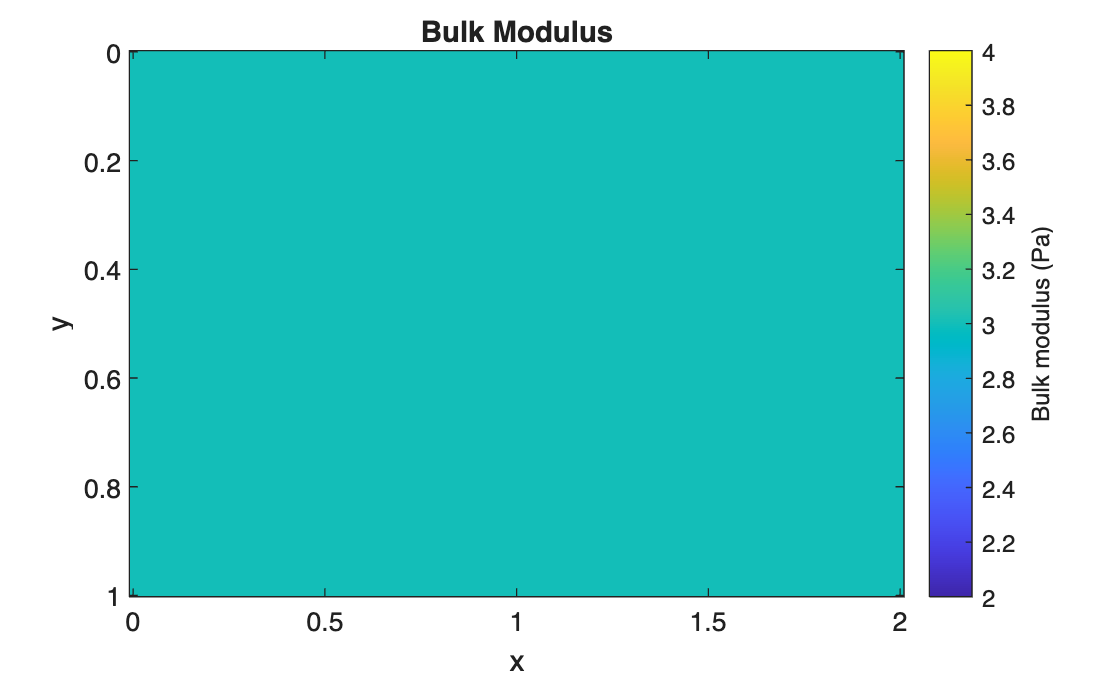

% Define a constant acoustic medium
medium_cnst = AcousticMedium2D.constant(KappaValue=3,BetaValue=4);

% Sample the medium onto the grids
[K_cnst,Bx_cnst,By_cnst] = sampleMedium2D(gsp_primal,medium_cnst);

figure
K_cnst.plot;
title("Bulk Modulus")

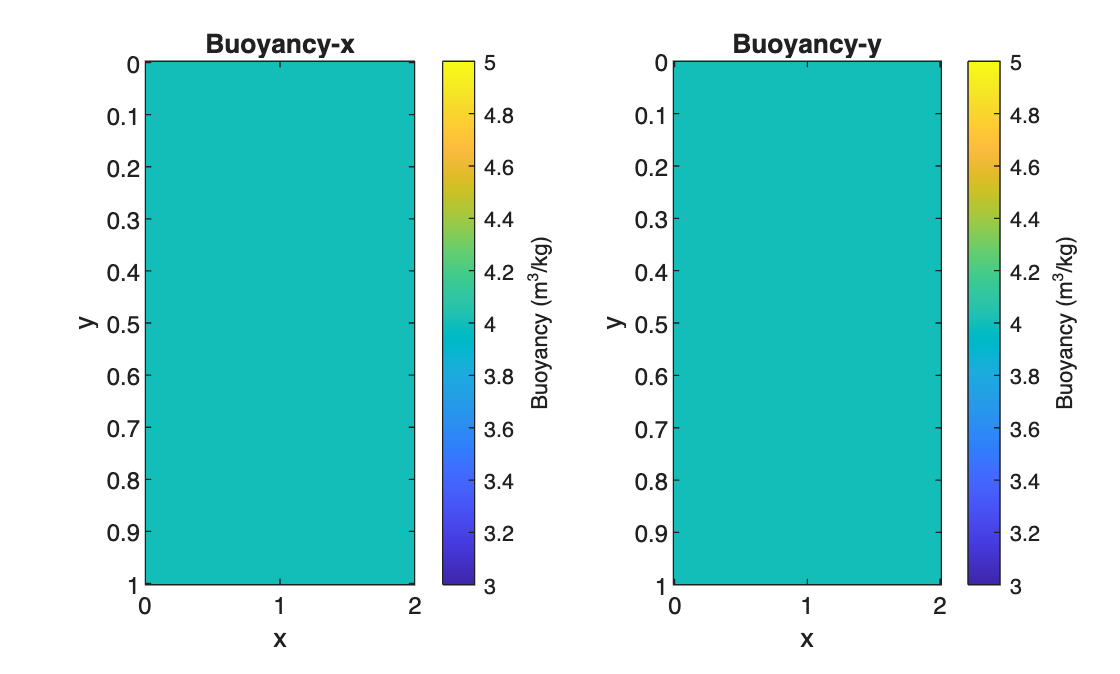


figure
tiledlayout(1,2)

nexttile
Bx_cnst.plot;
title("Buoyancy-x")

nexttile
By_cnst.plot;
title("Buoyancy-y")

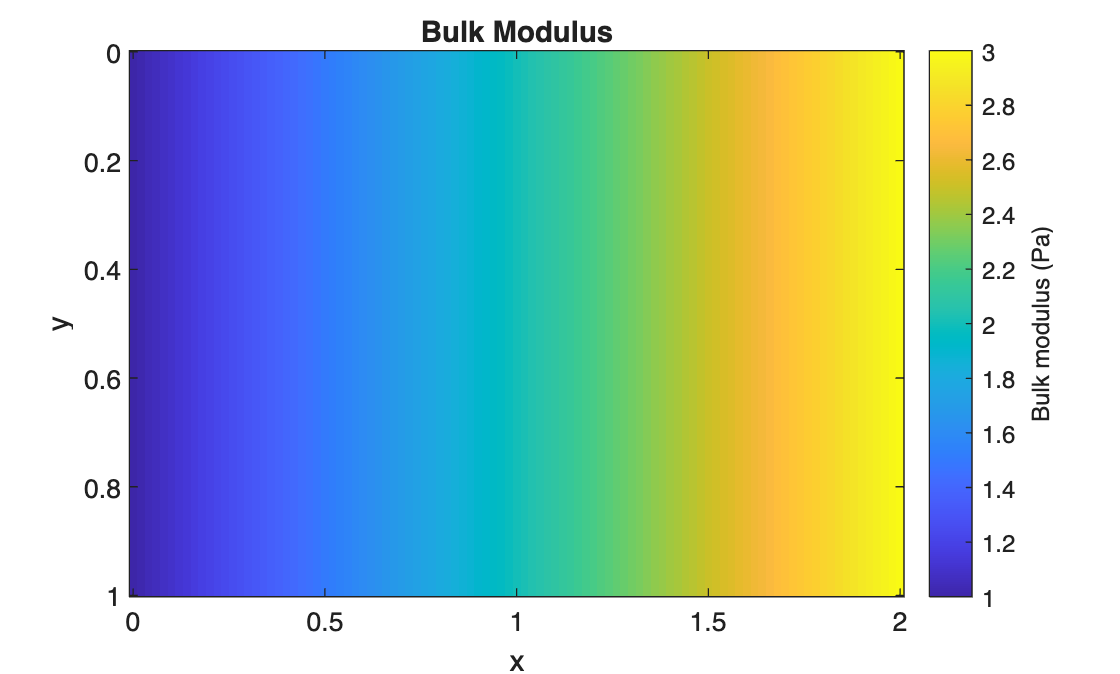

% Define linearly varying in x acoustic medium
medium_linearX = AcousticMedium2D.linearX( ...
    KappaRange=[1,3], ...
    BetaRange =[2,5], ...
    Domain    = [domain_x;domain_y]);

% Sample the medium onto the grids
[K_linearX,Bx_linearX,By_linearX] = sampleMedium2D(gsp_primal,medium_linearX);

figure
K_linearX.plot;
title("Bulk Modulus")

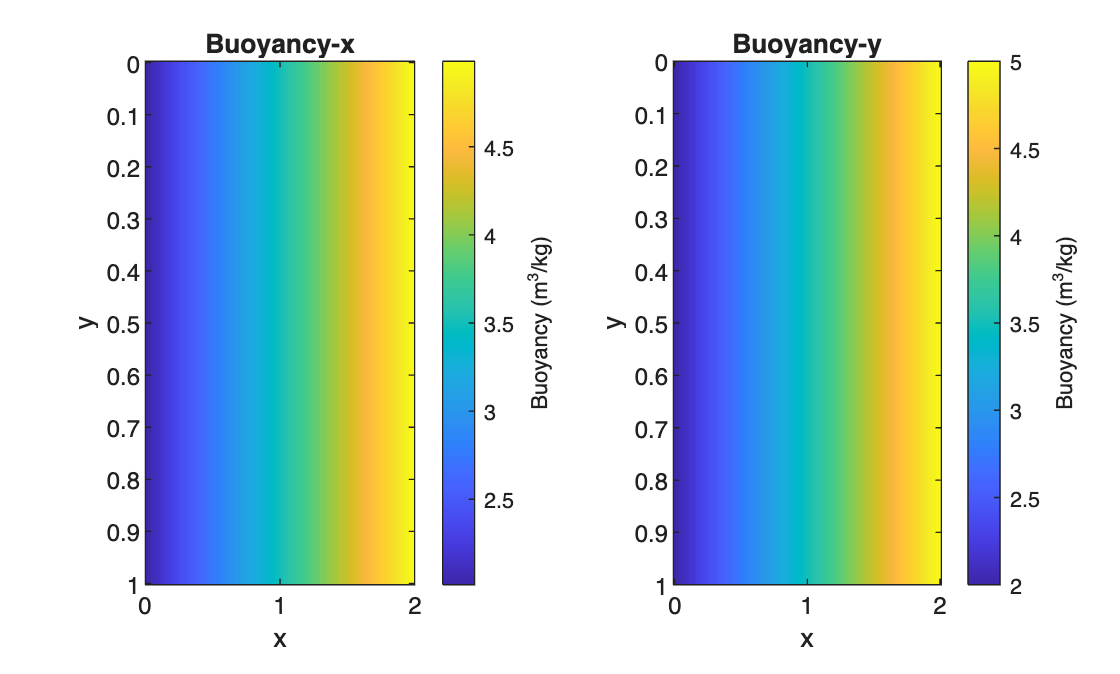


figure
tiledlayout(1,2);

nexttile
Bx_linearX.plot;
title("Buoyancy-x")

nexttile
By_linearX.plot;
title("Buoyancy-y")

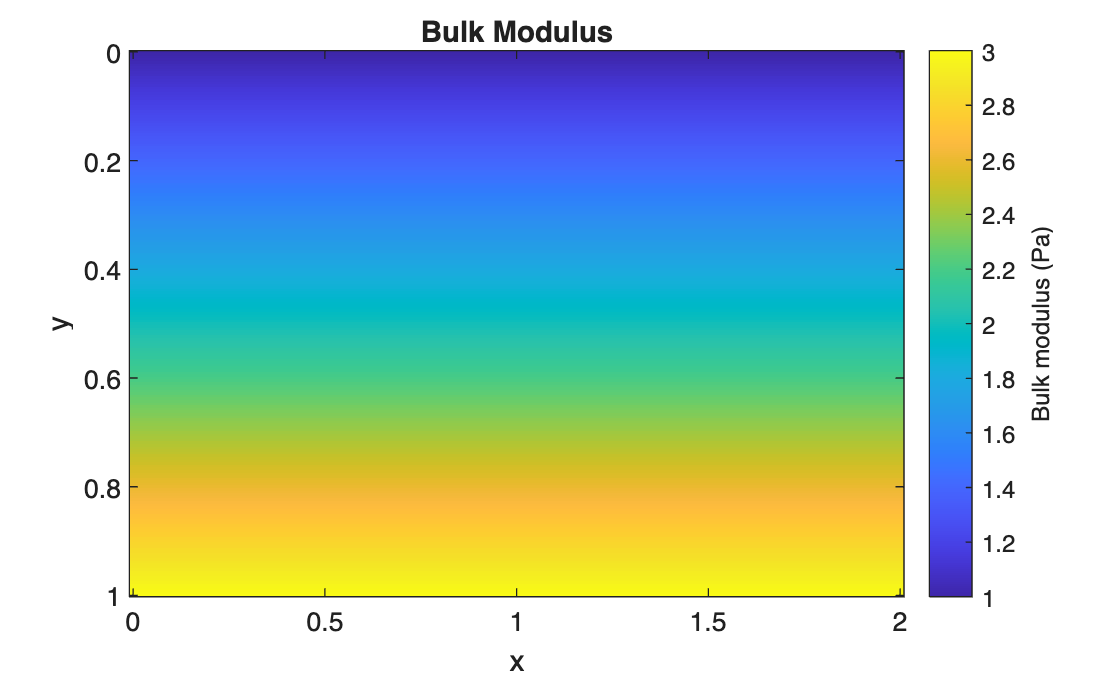

% Define linearly varying in y acoustic medium
medium_linearY = AcousticMedium2D.linearY( ...
    KappaRange= [1,3], ...
    BetaRange = [2,5], ...
    Domain    = [domain_x;domain_y]);

% Sample the medium onto the grids
[K_linearY,Bx_linearY,By_linearY] = sampleMedium2D(gsp_primal,medium_linearY);

figure
K_linearY.plot;
title("Bulk Modulus")

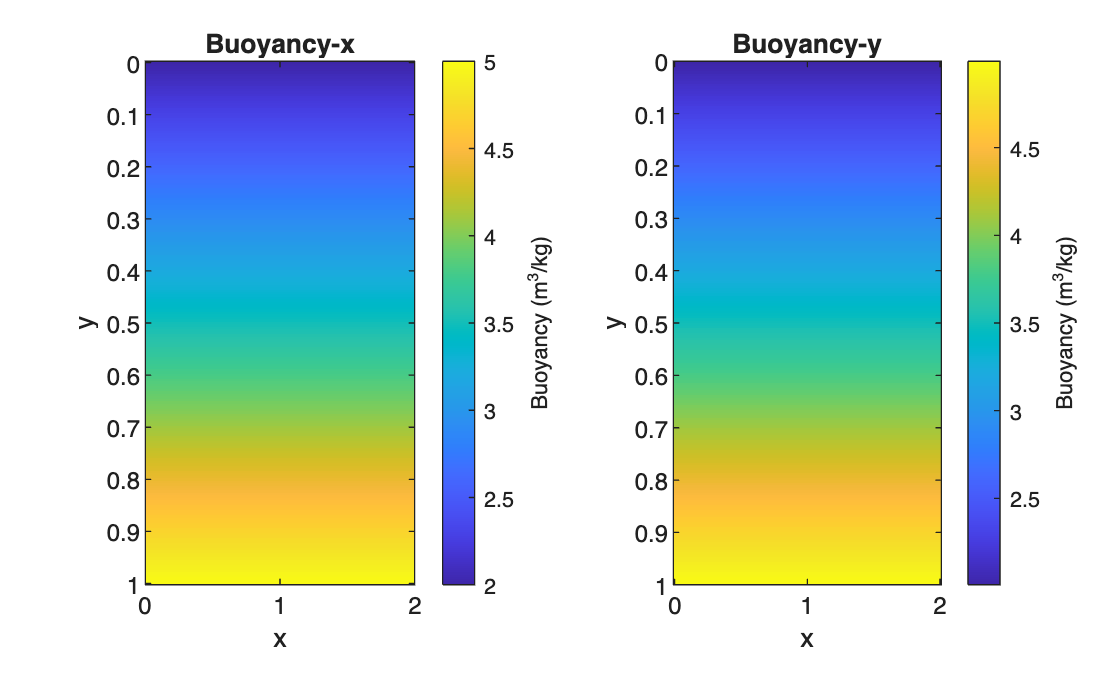


figure
tiledlayout(1,2);

nexttile
Bx_linearY.plot;
title("Buoyancy-x")

nexttile
By_linearY.plot;
title("Buoyancy-y")

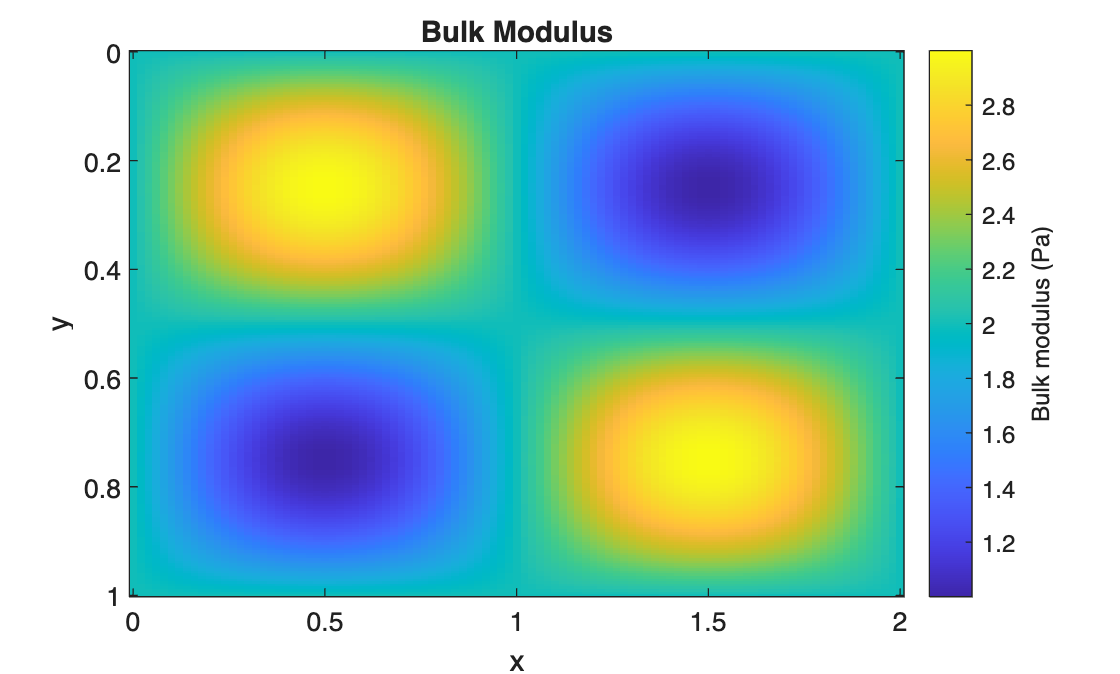

% Define smoothly varying acoustic medium
medium_smooth = AcousticMedium2D.smooth( ...
    KappaRange= [1,3], ...
    BetaRange = [2,5], ...
    Domain    = [domain_x;domain_y]);

% Sample the medium onto the grids
[K_smooth,Bx_smooth,By_smooth] = sampleMedium2D(gsp_primal,medium_smooth);

figure
K_smooth.plot;
title("Bulk Modulus")

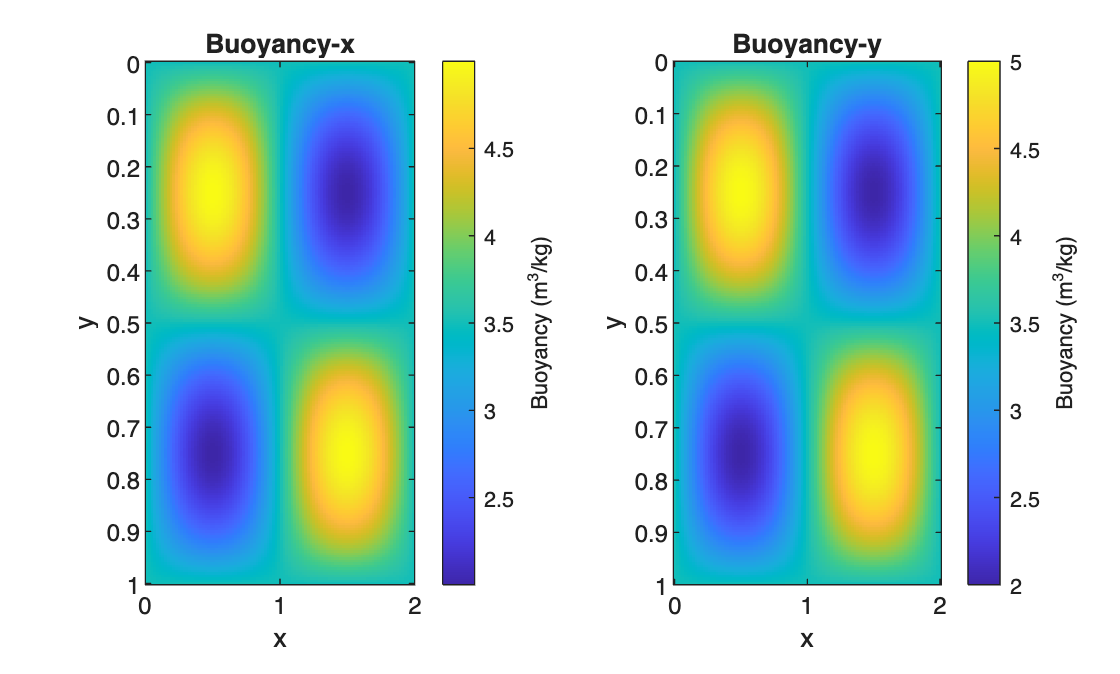


figure
tiledlayout(1,2)

nexttile
Bx_smooth.plot;
title("Buoyancy-x")

nexttile
By_smooth.plot;
title("Buoyancy-y")

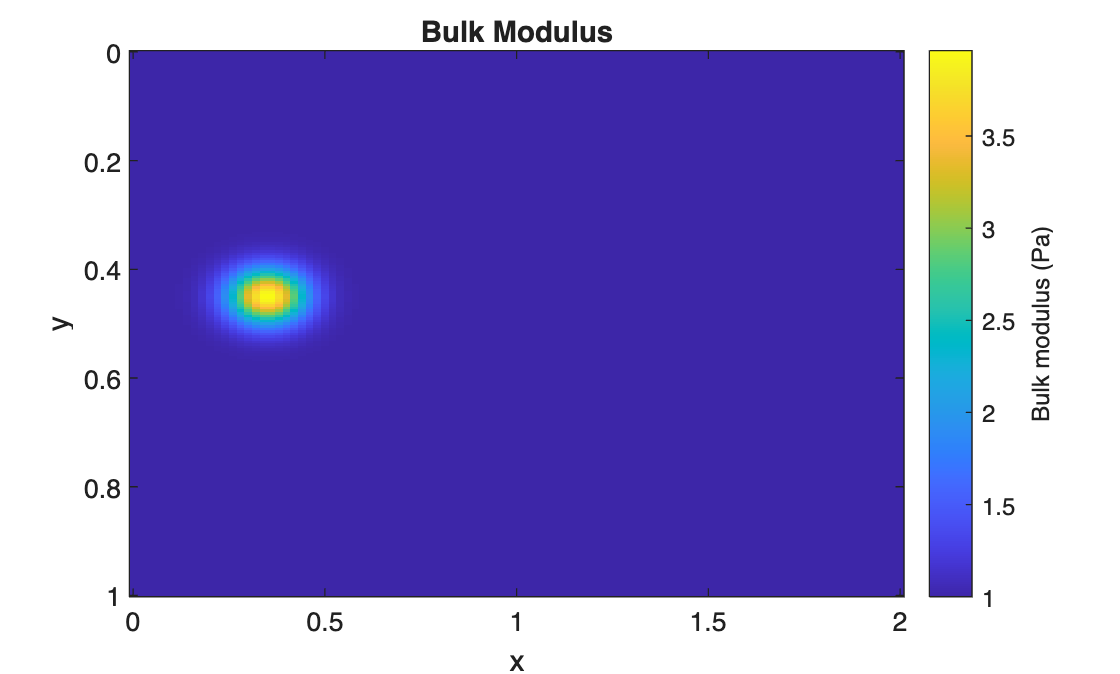

% Define acoustic medium with a Gaussian peak/dip 
medium_gauss = AcousticMedium2D.gaussian(...
    kappaInside=4,KappaOutside=1, ...
    BetaInside=2, BetaOutside=1, ...
    Center=[0.35,0.45],Width=[0.1,0.05]);

% Sample the medium onto the grids
[K_gauss,Bx_gauss,By_gauss] = sampleMedium2D(gsp_primal,medium_gauss);

figure
K_gauss.plot;
title("Bulk Modulus")

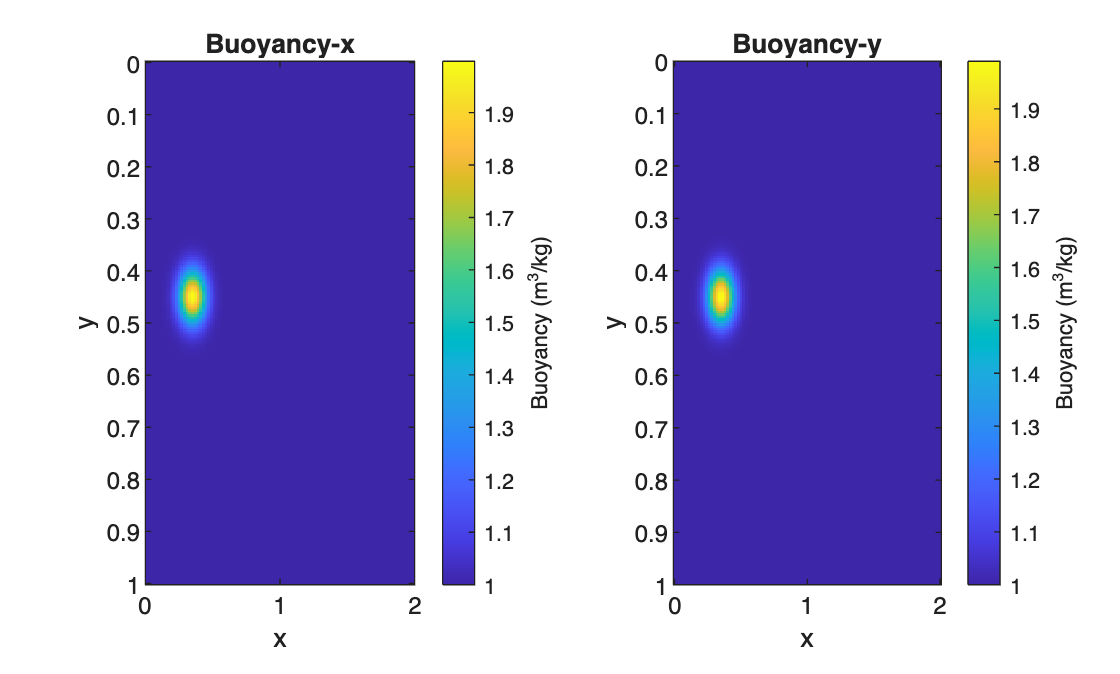


figure
tiledlayout(1,2)

nexttile
Bx_gauss.plot;
title("Buoyancy-x")

nexttile
By_gauss.plot;
title("Buoyancy-y")

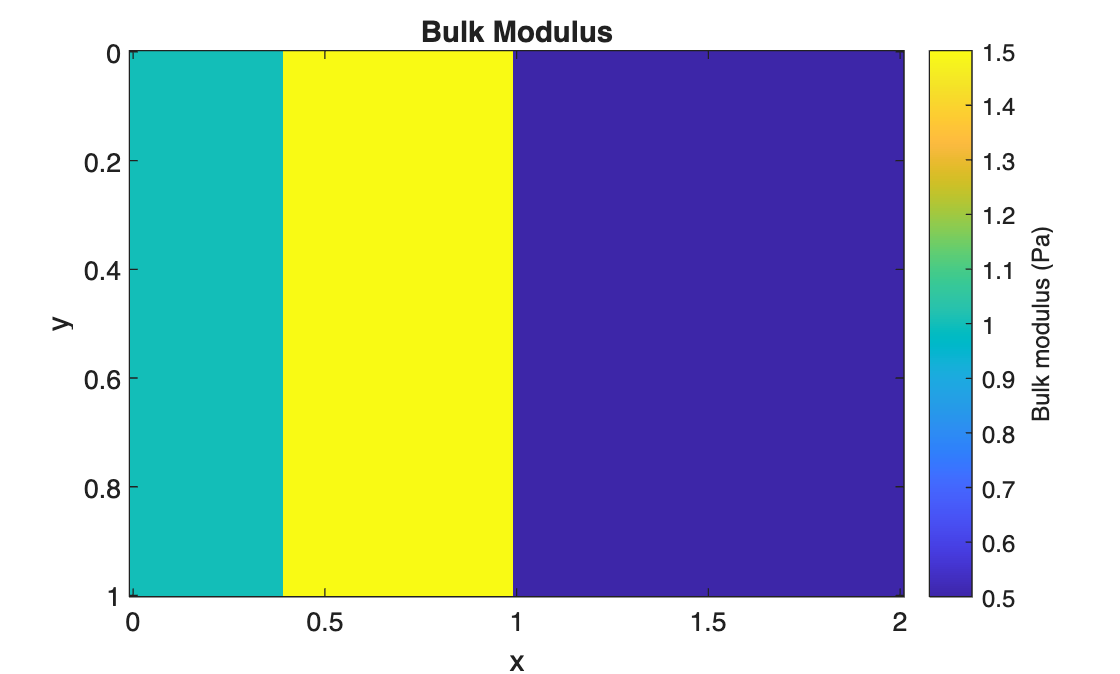

% Define acoustic medium with layers in x direction
medium_layX = AcousticMedium2D.layeredX( ...
    KappaValues   = [1,1.5,0.5], ...
    BetaValues    = [2,4,1], ...
    RelativeWidths= [0.2,0.3,0.5], ...
    Domain        = [domain_x;domain_y]);

% Sample the medium onto the grids
[K_layX,Bx_layX,By_layX] = sampleMedium2D(gsp_primal,medium_layX);

% Visualize the sampled medium properties
figure
K_layX.plot;
title("Bulk Modulus")

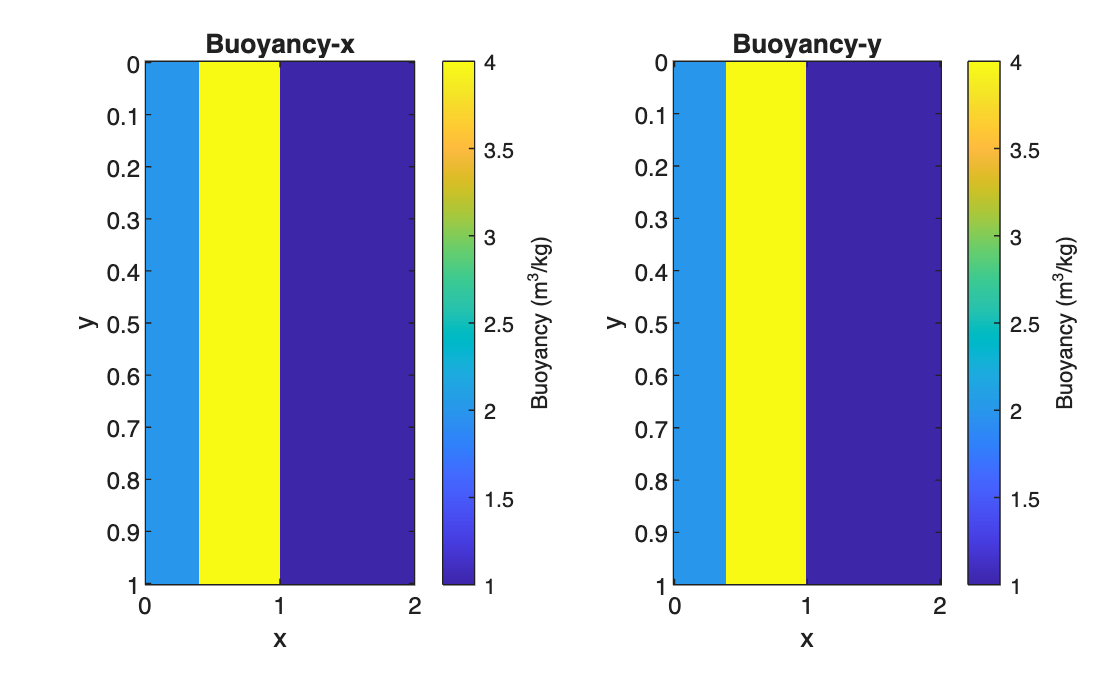


figure
tiledlayout(1,2)

nexttile
Bx_layX.plot;
title("Buoyancy-x")

nexttile
By_layX.plot;
title("Buoyancy-y")

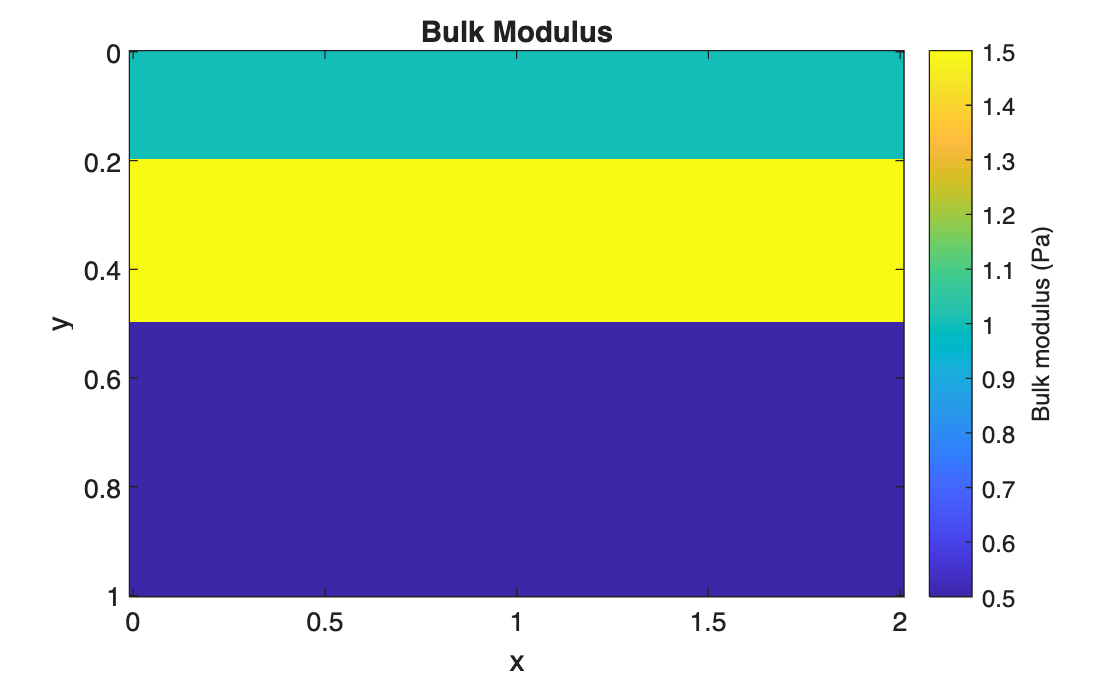

% Define acoustic medium with layers in y direction
medium_layY = AcousticMedium2D.layeredY( ...
    KappaValues   = [1,1.5,0.5], ...
    BetaValues    = [2,4,1], ...
    RelativeWidths= [0.2,0.3,0.5], ...
    Domain        = [domain_x;domain_y]);

% Sample the medium onto the grids
[K_layY,Bx_layY,By_layY] = sampleMedium2D(gsp_primal,medium_layY);

figure
K_layY.plot;
title("Bulk Modulus")

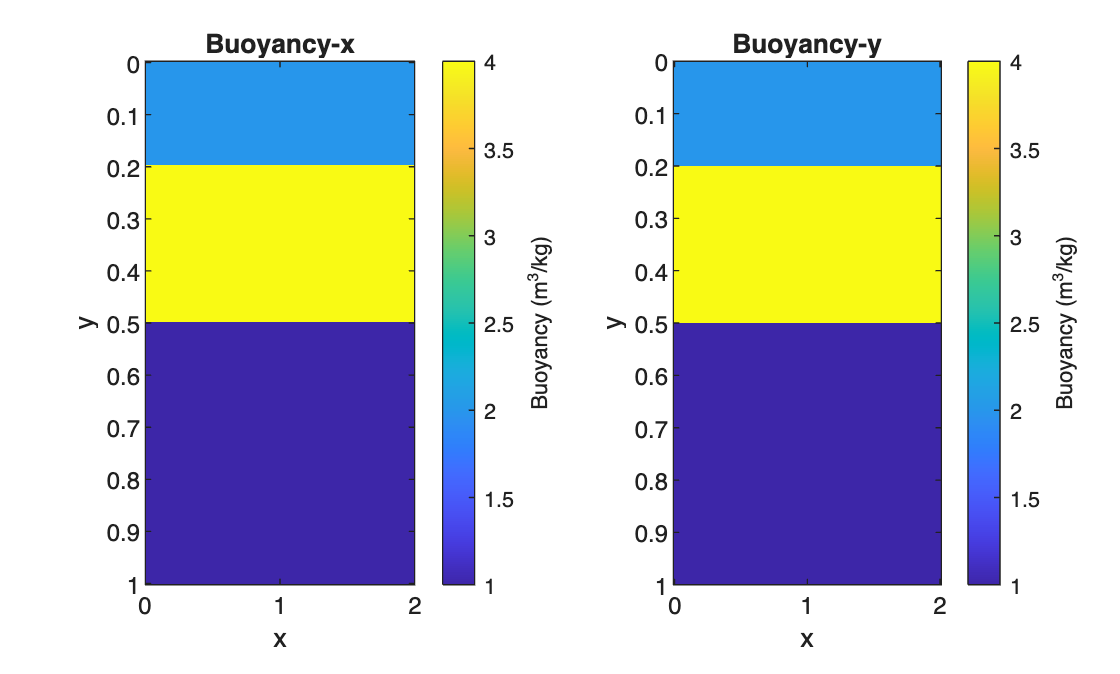


figure
tiledlayout(1,2)

nexttile
Bx_layY.plot;
title("Buoyancy-x")

nexttile
By_layY.plot;
title("Buoyancy-y")

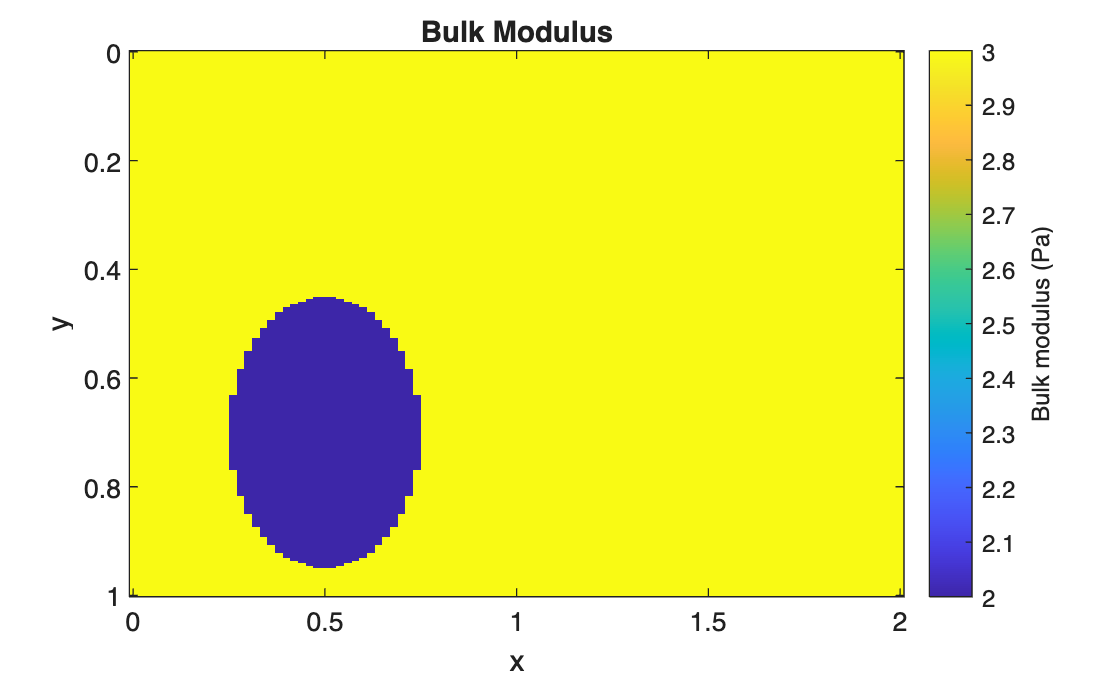

% Define acoustic medium with circular inclusion
medium_circ = AcousticMedium2D.circular( ...
    KappaInside  = 2, ...
    KappaOutside = 3, ...
    BetaInside   = 1, ...
    BetaOutside  = 4, ...
    Center       = [0.5,0.7], ...
    Radius       = 0.25);

% Sample the medium onto the grids
[K_circ,Bx_circ,By_circ] = sampleMedium2D(gsp_primal,medium_circ);

figure
K_circ.plot;
title("Bulk Modulus")

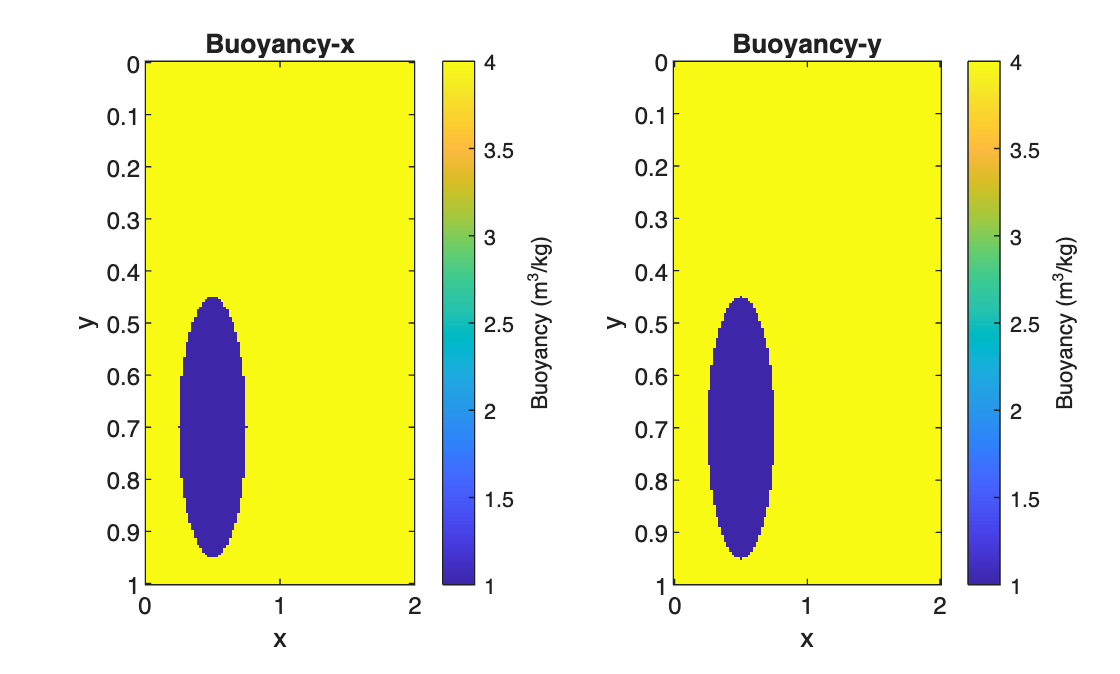


figure
tiledlayout(1,2)

nexttile
Bx_circ.plot;
title("Buoyancy-x")

nexttile
By_circ.plot;
title("Buoyancy-y")

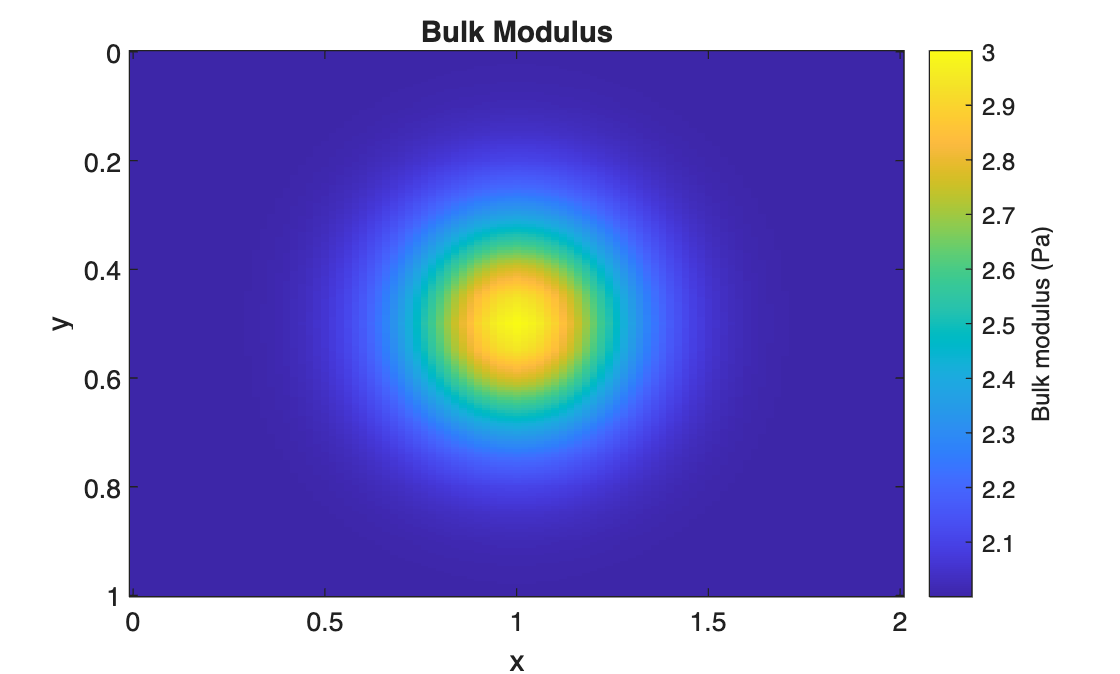

% Define acoustic medium from tabulated data

xData = linspace(0,2,41);
yData = linspace(0,1,21);

% ndgrid gives arrays with size [numel(xData),numel(yData)]
[XData,YData] = ndgrid(xData,yData);
kappaData = 2 + exp(-((XData-1)/0.3).^2-((YData-0.5)/0.2).^2);
betaData = 3 + 0.5*sin(pi*XData).*sin(2*pi*YData);

medium_tab = AcousticMedium2D.tabulated( ...
    XCoordinates=xData, ...
    YCoordinates=yData, ...
    KappaValues=kappaData, ...
    BetaValues=betaData, ...
    Method="linear", ...
    ExtrapolationMethod="none");

% Sample the medium onto the grids
[K_tab,Bx_tab,By_tab] = sampleMedium2D(gsp_primal,medium_tab);

figure
K_tab.plot;
title("Bulk Modulus")

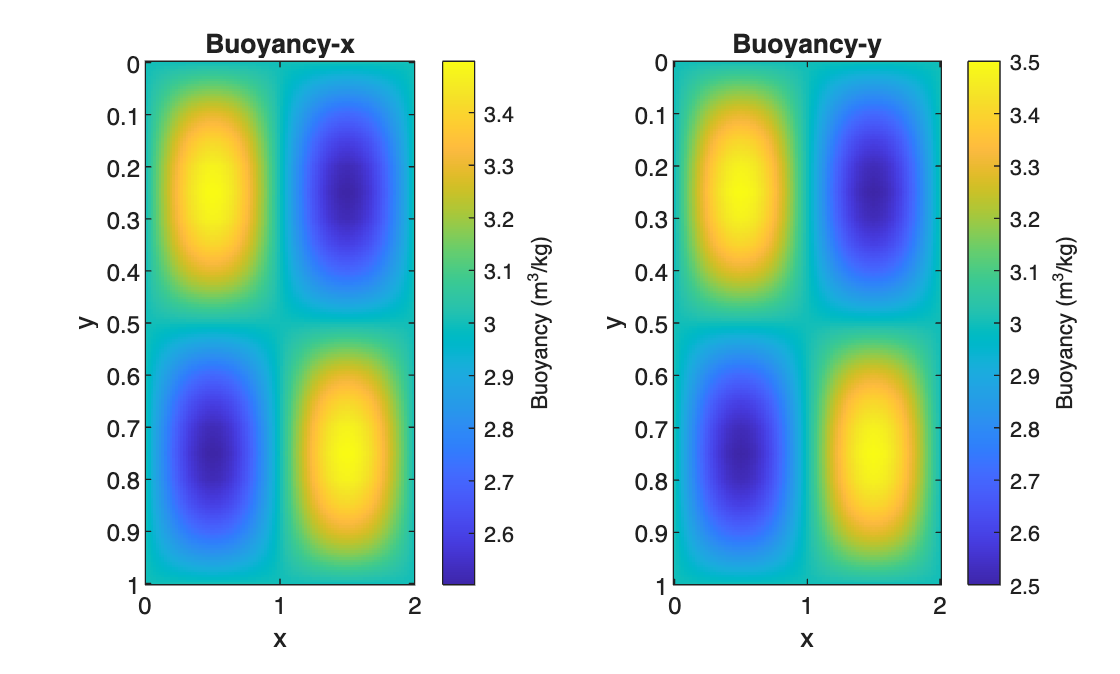


figure
tiledlayout(1,2)

nexttile
Bx_tab.plot;
title("Buoyancy-x")

nexttile
By_tab.plot;
title("Buoyancy-y")

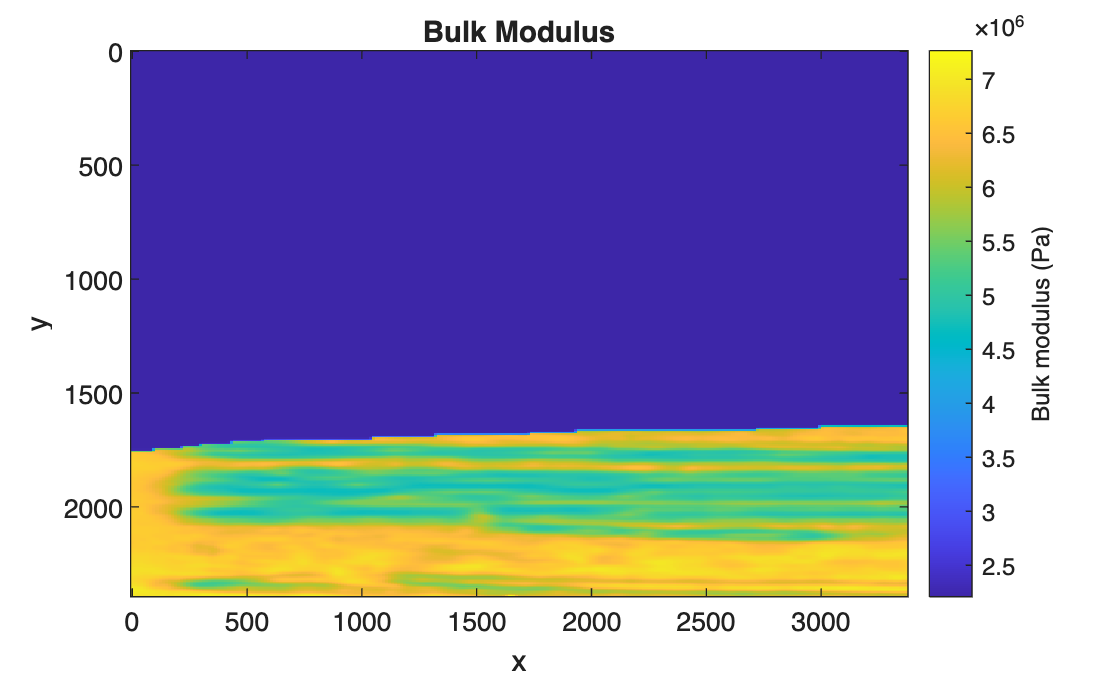

% Define acoustic medium from file data
projectRoot = currentProject().RootFolder;
matFile = fullfile(projectRoot, ...
    "src","utils","medium","mediumData",...
    "salt2D_data.mat");
data = load(matFile);

medium_salt = AcousticMedium2D.tabulated( ...
    XCoordinates=data.xData, ...
    YCoordinates=data.yData, ...
    KappaValues=data.kappaData, ...
    BetaValues=data.betaData);

% Construct sampling grid
grid_x = Grid1DUnifPrimal(data.xDom*0.05,251);
grid_y = Grid1DUnifPrimal(data.yDom*0.2,401);
gsp = GridSpace2D(grid_x,grid_y);

% Sample the medium onto the grids
[K_salt,Bx_salt,By_salt] = sampleMedium2D(gsp,medium_salt);

figure
K_salt.plot;
title("Bulk Modulus")

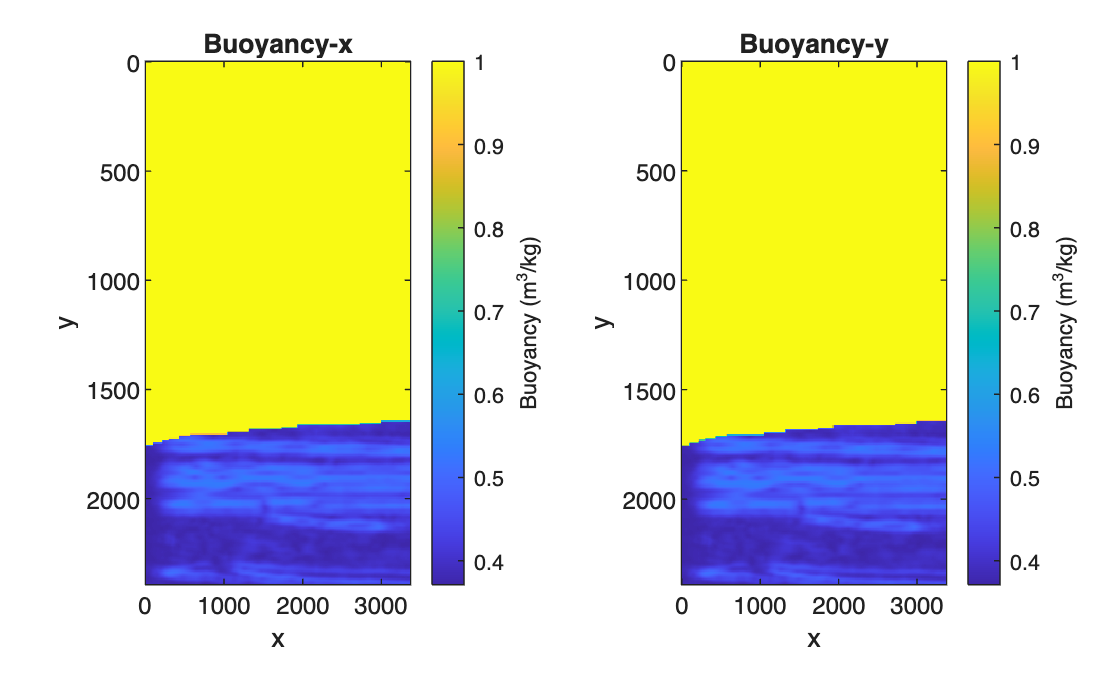


figure
tiledlayout(1,2)

nexttile
Bx_salt.plot;
title("Buoyancy-x")

nexttile
By_salt.plot;
title("Buoyancy-y")